# Solving Diferential Equation with Dirac

syms s t Y

,

f = '1 + 5*Dirac(t-5)'

f = '1 + 5*Dirac(t-5)'

F = laplace(f,t,s)

$$F = \frac{1}{s}+5\,\mathrm{laplace}\left(\mathrm{Dirac}\left(t-5\right),t,s\right)$$

F=1/s + 5*laplace(dirac(t - 5), t, s)

$$F = 5\,{\mathrm{e}}^{-5\,s}+\frac{1}{s}$$

Y1 = s*Y - 1

$$Y1 = Y\,s-1$$

Y2 = s*Y1 - 2

$$Y2 = s\,\left(Y\,s-1\right)-2$$

Sol = solve(Y2+2*Y1+10*Y-F,Y)

$$Sol = \frac{s+5\,{\mathrm{e}}^{-5\,s}+\frac{1}{s}+4}{s^{2}+2\,s+10}$$

sol = ilaplace(Sol,s,t)

$$sol = {\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)-\frac{\sin\left(3\,t\right)}{3}\right)-\frac{{\mathrm{e}}^{-t}\,\left(\cos\left(3\,t\right)+\frac{\sin\left(3\,t\right)}{3}\right)}{10}+\frac{4\,\sin\left(3\,t\right)\,{\mathrm{e}}^{-t}}{3}+\frac{5\,\mathrm{heaviside}\left(t-5\right)\,{\mathrm{e}}^{5-t}\,\sin\left(3\,t-15\right)}{3}+\frac{1}{10}$$

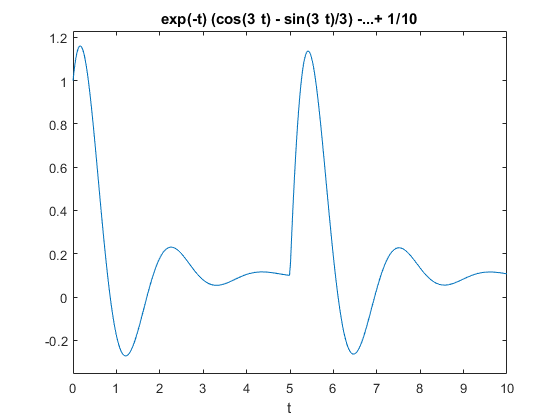

ezplot(sol,[0,10])